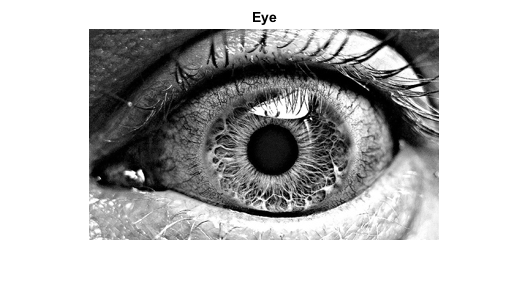

%HW5-1
% import grayscale image.
img = imread("eye.png");
imshow(img)
title("Eye")

Eye_mean = mean2(img)

Eye_mean = 114.9630

Eye_std = std2(img)

Eye_std = 79.0944

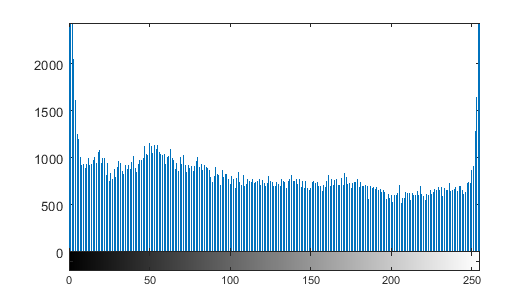

imhist(img)

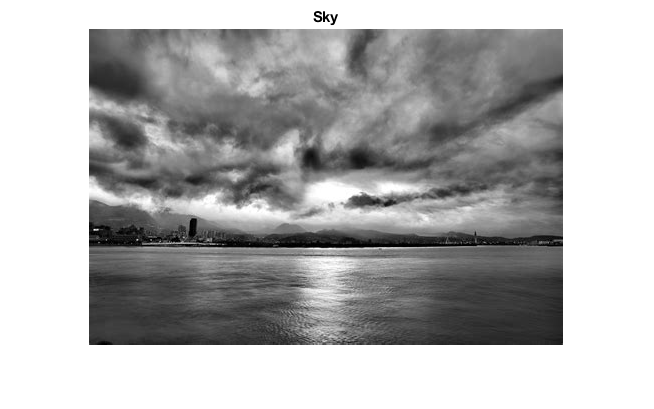

%similar image
sky = imread("sky.png");
imshow(sky)
title("Sky")

sky_mean = mean2(sky)

sky_mean = 115.4467

sky_std = std2(sky)

sky_std = 48.0025

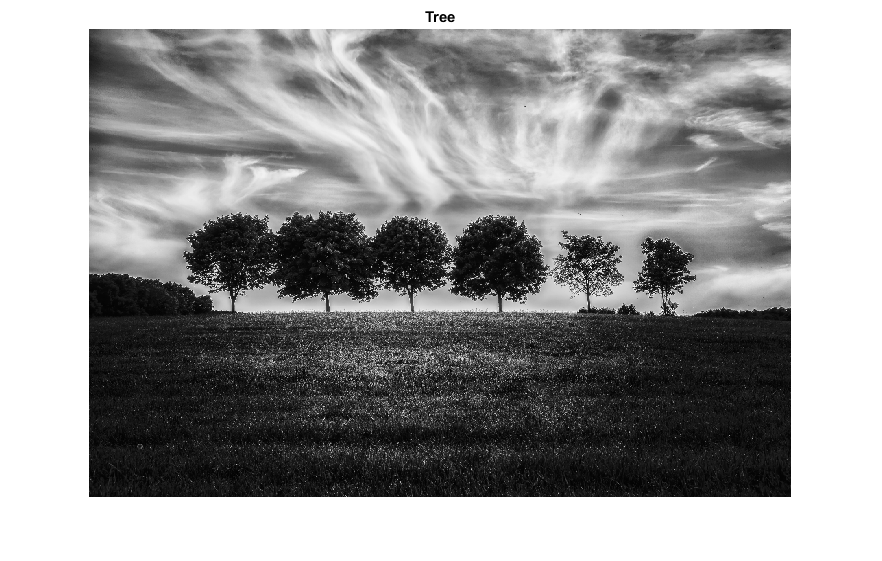

%different image
tree = imread("Tree.png");
imshow(tree)
title("Tree")

Eye_mean = mean2(tree)

Eye_mean = 100.5167

Eye_std = std2(tree)

Eye_std = 74.7046

%Q2--graycomatrix
%Create gray-level co-occurrence matrix from image
I = imread('cell.tif');
imshow(I)
title("Cell")
offsets = [0 1; -1 1;-1 0;-1 -1];

[glcms,SI] = graycomatrix(I,'Offset',offsets);
imshow(rescale(SI))


whos

%HW5-Q3

%HW6

%Q1
IQ1 = imread('coins.png');
imshow(IQ1)

%Convert the image to a binary image.
%bwtraceboundary and bwboundaries only work with binary images.
BW = imbinarize(IQ1);
imshow(BW)

%Determine the row and column coordinates of a pixel on the border of the object you want to trace. bwboundary uses this point as the starting location for the boundary tracing.
dim = size(BW)


col = round(dim(2)/2)-90;
row = find(BW(:,col), 1 )

%Call bwtraceboundary to trace the boundary from the specified point. As required arguments, you must specify a binary image, the row and column coordinates of the starting point, and the direction of the first step. The example specifies north ( 'N' ).
boundary = bwtraceboundary(BW,[row, col],'N');

%Display the original grayscale image and use the coordinates returned by bwtraceboundary to plot the border on the image.
imshow(IQ1)
hold on;
plot(boundary(:,2),boundary(:,1),'g','LineWidth',3);


imshow(IQ1)
hold on;
plot(boundary(:,2),boundary(:,1),'g','LineWidth',3);
BW_filled = imfill(BW,'holes');
boundaries = bwboundaries(BW_filled);
%Plot the borders of all the coins on the original grayscale image using the coordinates returned by bwboundaries .

for k=1:10
   b = boundaries{k};
   plot(b(:,2),b(:,1),'g','LineWidth',3);
end

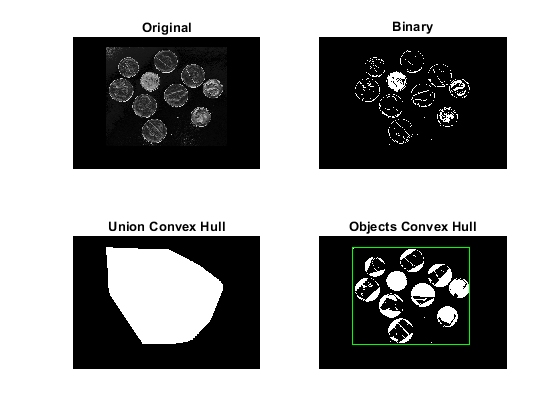

%Q2
subplot(2,2,1);
I = imread('coins.png');
imshow(I);
title('Original');

subplot(2,2,2);
BW = I > 100;
imshow(BW);
title('Binary');

subplot(2,2,3);
CH = bwconvhull(BW);
imshow(CH);
title('Union Convex Hull');

subplot(2,2,4);
CH_objects = bwconvhull(BW,'objects');
imshow(CH_objects);
title('Objects Convex Hull');
stats = regionprops(CH, 'BoundingBox', 'MajorAxisLength','MinorAxisLength');
rectangle('Position', stats.BoundingBox,'EdgeColor','g');

stats

stats = struct with fields:
        BoundingBox: [83.5000 27.5000 291 242]
    MajorAxisLength: 300.4371
    MinorAxisLength: 228.8574


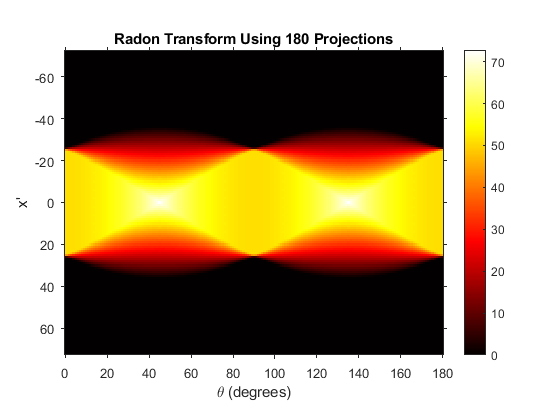

%Q3
iptsetpref('ImshowAxesVisible','on')
%Create a sample image.
IQ3 = zeros(100,100);
IQ3(25:75, 25:75) = 1;
%Calculate the Radon transform.
theta = 0:180;
[R,xp] = radon(IQ3,theta);
%Display the transform.
imshow(R,[],'Xdata',theta,'Ydata',xp,'InitialMagnification','fit')
title('Radon Transform Using 180 Projections')
xlabel('\theta (degrees)')
ylabel('x''')
colormap(gca,hot), colorbar

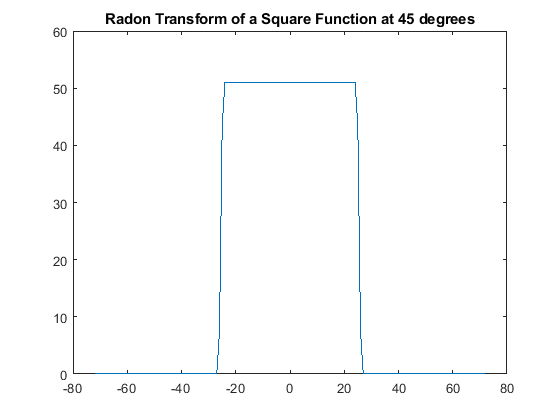

figure
plot(xp,R(:,2)); 
title('Radon Transform of a Square Function at 45 degrees')

%Make the axes scale invisible.
iptsetpref('ImshowAxesVisible','off')

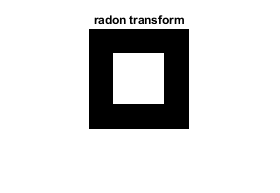

%Q4
imshow(IQ3)
title("radon transform")

Q4mean = mean2(IQ3)

Q4mean = 0.2601

Q4std = std2(IQ3)

Q4std = 0.4387

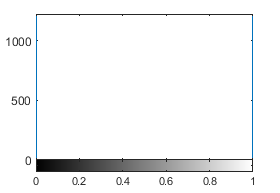

imhist(IQ3)

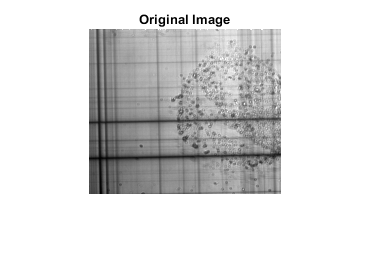

%Q5
%Compute the Radon Transform of an Image
%Read an image into the workspace. Convert it into a grayscale image.
IQ5 = fitsread("solarspectra.fts");
IQ5 = rescale(IQ5);
%Display the original image.
figure
imshow(IQ5)
title("Original Image")

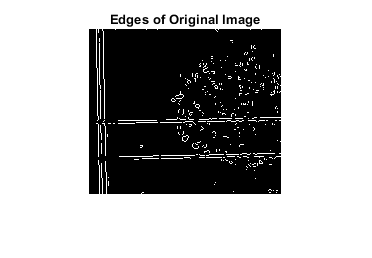

%Compute a binary edge image using the edge function. Display the binary image returned by the edge function.
BW = edge(IQ5);
figure
imshow(BW)
title("Edges of Original Image")

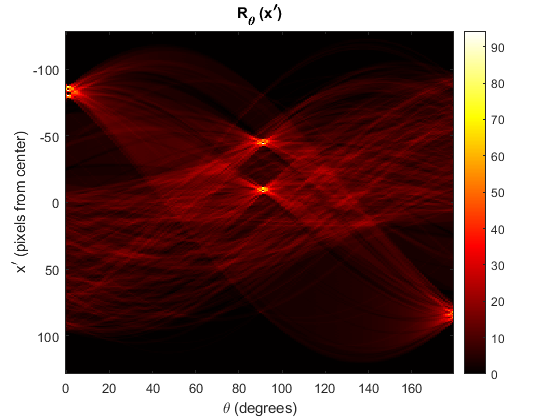

%Calculate the Radon transform of the image, using the radon function. The locations of peaks in the transform correspond to the locations of straight lines in the original image.
theta = 0:179;
[R,xp] = radon(BW,theta);
%Display the result of the Radon transform.
figure
imagesc(theta,xp,R)
colormap(hot)
xlabel("\theta (degrees)")
ylabel("x^{\prime} (pixels from center)")
title("R_{\theta} (x^{\prime})")
colorbar

%stats & histogram
Q5mean = mean2(IQ5)

Q5mean = 0.5840

Q5std = std2(IQ5)

Q5std = 0.1579

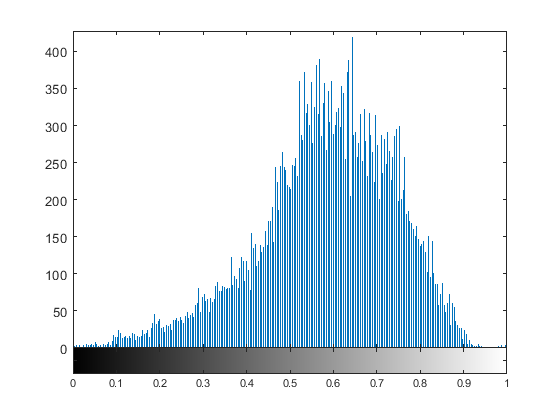

imhist(IQ5)